% Store all 410 dicom images size
clear all;
close all;
clc;

size_array = zeros(410, 2)

size_array =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0



folder_path = 'D:\Studying\RetinaNet_Project\all_DICOM_files\AllDICOMs';
file_pattern = fullfile(folder_path, '*.dcm'); % Change to whatever pattern you need.
INbreasst_mammograms = dir(file_pattern);

for i = 1:410
    current_mammogram = INbreasst_mammograms(i).name;
    current_mammogram_size = size(dicomread(current_mammogram));
    size_array(i, 1) = current_mammogram_size(1);
    size_array(i, 2) = current_mammogram_size(2);
end

% Store 410 mammograms file paths and corresponding mass coordinates
clear all;
close all;
clc;


load INbreast_mass_statistic_struct.mat;

folder_path = 'D:\Studying\RetinaNet_Project\all_DICOM_files\AllDICOMs';
file_pattern = fullfile(folder_path, '*.dcm'); % Change to whatever pattern you need.
INbreasst_mammograms = dir(file_pattern);

% Pointer for going through 343 .mat files.
pointer_1 = 1;
% Pointer for going through 410 .dcm files.
pointer_2 = 1;

while pointer_1 < 343
    % First compare whether the file names match, since there are more
    % .dcm files than .mat files.
    
    % Get current .mat file number.
    current_mat_file_name = split(INbreasst_mass_statistic(pointer_1).name, "_");
    current_mat_file_name = current_mat_file_name{1};
    % Get current .dcm file number.
    current_dicom_file_name = split(INbreasst_mammograms(pointer_2).name, "_");
    current_dicom_file_name = current_dicom_file_name{1};
    
    % If match, copy the struct fields.
    if (strcmp(current_mat_file_name, current_dicom_file_name))
        INbreasst_mammograms(pointer_2).mass_contour = INbreasst_mass_statistic(pointer_1).mass_contour;
        INbreasst_mammograms(pointer_2).mass_bbox = INbreasst_mass_statistic(pointer_1).mass_bbox;
        INbreasst_mammograms(pointer_2).mass_area = INbreasst_mass_statistic(pointer_1).mass_area;
        INbreasst_mammograms(pointer_2).mass_bbox_floor_and_ceil = INbreasst_mass_statistic(pointer_1).mass_bbox_floor_and_ceil;
        INbreasst_mammograms(pointer_2).mass_area_floor_and_ceil = INbreasst_mass_statistic(pointer_1).mass_area_floor_and_ceil;
        % Move the pointer to next index, respectively.
        pointer_1 = pointer_1 + 1;
        pointer_2 = pointer_2 + 1;
    else
        % Not match, only move the pointer_2 which is the pointer for
        % all .dcm file.
        % This make senses since in both struct, names are in order.
        pointer_2 = pointer_2 + 1;
    end
    
    
end


% Store the size of mammograms into the struct.

clear all;
close all;
clc;

load INbreast_mammograms_size.mat;
load INbreast_mammogram_statistic_struct.mat;
load INbreast_mass_statistic_struct.mat;

cell_temp = cell(1, 1);
for i = 1:410
    cell_temp{1} = size_array(i, :);
    INbreasst_mammograms_statistic_struct(i).mammogram_size = cell_temp;
end

% Store the coordinates for bounding box, in format of PIL
% Just switch the position of values.
% Note that for the original bbox coordinates that I stored,
% when plot dicom images, the coordinate axis has changed!

clear all;
close all;
clc;

load INbreast_mammogram_statistic_struct.mat;
for i = 1:410
    current_mammogram = INbreasst_mammograms_statistic_struct(i);
    current_num_of_mass = length(INbreasst_mammograms_statistic_struct(i).mass_bbox);
    cell_temp = cell(1, current_num_of_mass);
    current_mammogram_size = current_mammogram.mammogram_size{1};
    for j = 1:current_num_of_mass
        coordinate_temp = zeros(1, 4);
        current_mass_bbox = current_mammogram.mass_bbox_floor_and_ceil{j}
        % Assign the new values based on relationship.
        % Note that since in numpy the array index starts from 0(in Python)
        % Here I subtract one from each entry.
        % Assign left
        coordinate_temp(1) = current_mass_bbox(1) - 1;
        % Assign top
        coordinate_temp(2) = current_mass_bbox(3) - 1;
        % Assign right
        coordinate_temp(3) = current_mass_bbox(2) - 1;
        % Assign below
        coordinate_temp(4) = current_mass_bbox(4) - 1;    
        cell_temp{j} = coordinate_temp;
    end
    INbreasst_mammograms_statistic_struct(i).mass_bbox_for_PIL = cell_temp;
    
end

current_mass_bbox =         2392        2492         982        1098


current_mass_bbox =         3110        3328        1007        1203


current_mass_bbox =          124         312        2040        2203


current_mass_bbox =         1798        1890        1283        1397


current_mass_bbox =         2464        2701         813         966


current_mass_bbox =          152         371        2378        2557


current_mass_bbox =         2760        3078         547         770


current_mass_bbox =         2427        2741         878        1113


current_mass_bbox =          197         364        1090        1263


current_mass_bbox =          749         884         918        1045


current_mass_bbox =         1544        2139        1085        1795


current_mass_bbox =         1333        1997        1287        2053


current_mass_bbox =         1986        2170        1933        2138


current_mass_bbox =         2009        2189        2190        2342


current_mass_bbox =          102         281         865        1101


current_mass_bbox =          104         283        1479        1735


current_mass_bbox =            1         371        1508        1892


current_mass_bbox =            5         346        2114        2403


current_mass_bbox =          178         862         495        1025


current_mass_bbox =           32         710         938        1468


current_mass_bbox =            0         799        1034        1760


current_mass_bbox =           24         248        1597        1837


current_mass_bbox =          698         957        1207        1414


current_mass_bbox =         1980        2413         876        1295


current_mass_bbox =         2343        2483         691         858


current_mass_bbox =         1647        2062         940        1372


current_mass_bbox =         2101        2243         884        1019


current_mass_bbox =          710        1009        1744        2096


current_mass_bbox =          605         964        2255        2580


current_mass_bbox =         1719        1962        1270        1484


current_mass_bbox =         1364        1514        1499        1725


current_mass_bbox =         1914        2429        1176        1634


current_mass_bbox =         1830        2223        1942        2408


current_mass_bbox =          357         494        2108        2275


current_mass_bbox =          277         796        1163        1642


current_mass_bbox =         1678        2133        1098        1706


current_mass_bbox =           44         531        1636        2069


current_mass_bbox =         2350        3328        1770        2755


current_mass_bbox =          316         456        1039        1143


current_mass_bbox =         2197        3121        2931        3659


current_mass_bbox =          584         737        2458        2590


current_mass_bbox =            5         542        1418        1998


current_mass_bbox =          371         965        1220        1888


current_mass_bbox =         2850        2999        1036        1204


current_mass_bbox =         2455        2941        1173        1632


current_mass_bbox =         2340        2792         926        1386


current_mass_bbox =         1950        2329        1484        1889


current_mass_bbox =         1871        2410        1706        2127


current_mass_bbox =          165         487        1520        1820


current_mass_bbox =          339         709        1322        1579


current_mass_bbox =           44         562        2506        2903


current_mass_bbox =            0         350        2466        2912


current_mass_bbox =    155   343   325   530


current_mass_bbox =          527         731        1087        1292


current_mass_bbox =         2820        3280        1137        1469


current_mass_bbox =         2419        2847        1164        1510


current_mass_bbox =         1889        2099        1078        1302


current_mass_bbox =         1569        1819        1251        1557


current_mass_bbox =          220         659         692        1277


current_mass_bbox =          308         741         987        1470


current_mass_bbox =         3066        3329         611         838


current_mass_bbox =         3040        3324        1222        1408


current_mass_bbox =         3041        3289        2551        2792


current_mass_bbox =         2691        2975        1811        2069


current_mass_bbox =           97         402        1611        1938


current_mass_bbox =           -1         309        2208        2458


current_mass_bbox =         1995        2449        1696        2272


current_mass_bbox =         2193        2560        2237        2730


current_mass_bbox =          448         971        1618        2020


current_mass_bbox =          598        1097        1378        1745


current_mass_bbox =           69         220        2586        2739


current_mass_bbox =         1840        2005        3253        3343


current_mass_bbox =          447         566        1886        2021


current_mass_bbox =         1904        2072        2608        2747


current_mass_bbox =          605        1101        1048        1664


current_mass_bbox =          279         823        1803        2393


current_mass_bbox =           43         978        1861        2680


current_mass_bbox =            1         451        1867        2630


current_mass_bbox =         2974        3183        1491        1767


current_mass_bbox =         3085        3300        1005        1205


current_mass_bbox =         2562        3022        1912        2494


current_mass_bbox =         2257        2712        1657        2264


current_mass_bbox =          132         234        2144        2291


current_mass_bbox =          136         309        1753        1950


current_mass_bbox =          586         855         934        1278


current_mass_bbox =          862        1140        1495        1736


current_mass_bbox =         2196        2417         330         537


current_mass_bbox =         2233        2464         825        1079


current_mass_bbox =         2274        2362        2432        2496


current_mass_bbox =         1651        1725        1512        1562


current_mass_bbox =         1977        2054        1201        1273


current_mass_bbox =         1865        2179        1376        1697


current_mass_bbox =         2213        2524        1199        1530


current_mass_bbox =         2748        2949        1438        1621


current_mass_bbox =         2934        3237        1183        1444


current_mass_bbox =         2070        2262        1112        1307


current_mass_bbox =         2245        2467        1148        1437


current_mass_bbox =          980        1371        1792        2223


current_mass_bbox =          861        1284        1606        2061


current_mass_bbox =         1983        2178        2603        2719


current_mass_bbox =         1964        2131        2420        2517


current_mass_bbox =          624         819        2362        2565


current_mass_bbox =          439         546        1482        1610


current_mass_bbox =          351         553        1548        1723


current_mass_bbox =          968        1057        3166        3232


current_mass_bbox =          134         413        2400        2637


current_mass_bbox =          161         488        1653        1992


current_mass_bbox =         1761        1864        1674        1805


current_mass_bbox =         1905        2081         839        1004


current_mass_bbox =           89         797        1217        2109


current_mass_bbox =           64         820        1612        2418


current_mass_bbox =         1403        1565        3013        3155


current_mass_bbox =         1337        1527        2614        2790


current_mass_bbox =          425         948        1732        2100


current_mass_bbox =          201         732        2442        2703


current_mass_bbox =         3167        3329        2026        2153


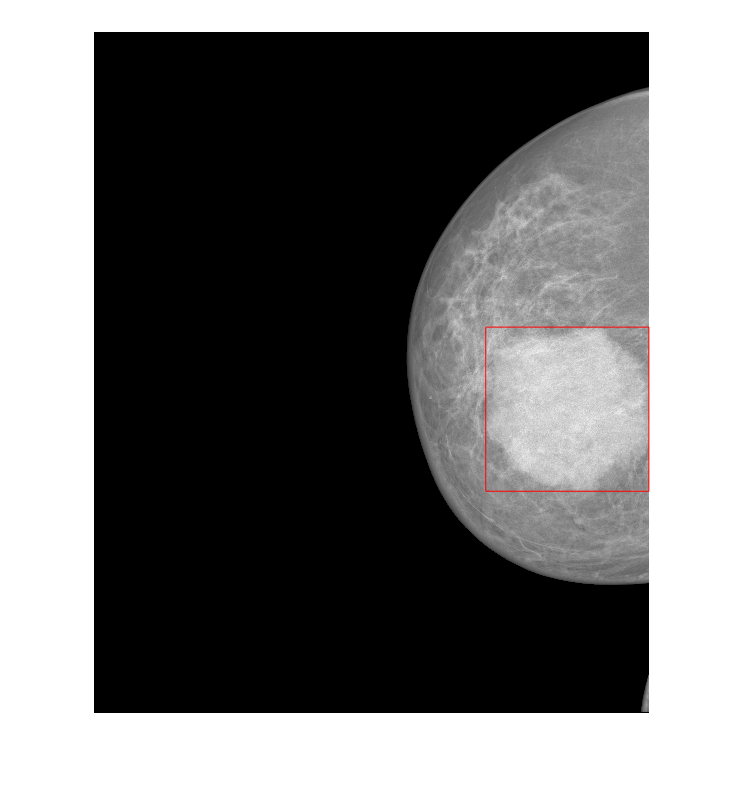

% Test whether the resulting data from above is correct.

clear all;
close all;
clc;

load INbreast_mammogram_statistic_struct.mat;

index = 73;
data = dicomread(INbreasst_mammograms_statistic_struct(index).name);
mass_bbox = INbreasst_mammograms_statistic_struct(index).mass_bbox_floor_and_ceil{1};

imshow(data, []);
rectangle('Position', [mass_bbox(1), mass_bbox(3), mass_bbox(2) - mass_bbox(1), ...
    mass_bbox(4) - mass_bbox(3)], "EdgeColor", 'r')